# Analyse de Donées - TD2

Analyse Discriminante - Les iris de Fisher

09_11_22

clc; clear all; close all;

1. Charger le fichier

load fisheriris.mat

2. Reproduire la figure 1 de la page 7

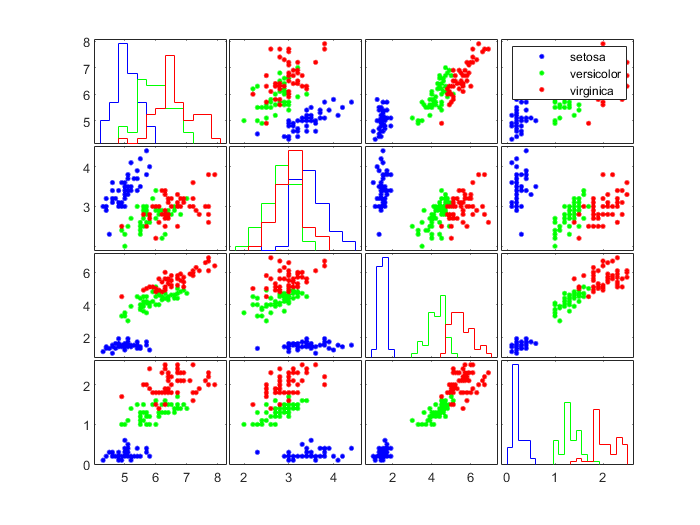

gplotmatrix(meas, [], species)

3. Calculer table 1 de la page 7

%M = min(meas(:,1))
m_min = min(meas);
m_qu1 = quantile(meas, 1/4);
m_med = median(meas);
m_mean = mean(meas);
m_qu3 = quantile(meas, 3/4);
m_max = max(meas);

matrix = [m_min; m_qu1; m_med; m_mean; m_qu3; m_max]

matrix =     4.3000    2.0000    1.0000    0.1000
    5.1000    2.8000    1.6000    0.3000
    5.8000    3.0000    4.3500    1.3000
    5.8433    3.0573    3.7580    1.1993
    6.4000    3.3000    5.1000    1.8000
    7.9000    4.4000    6.9000    2.5000


4 . Reproduire la figure 2 de la page 8

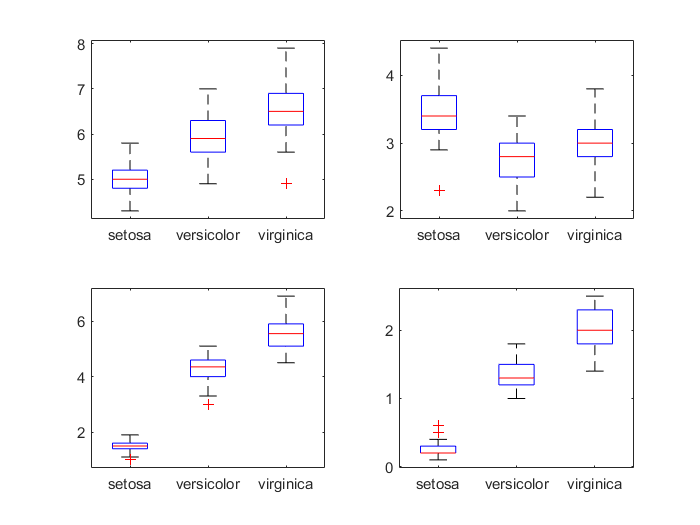

figure;
for i = 1 : 4
    subplot(2,2,i)
    boxplot(meas(:,i),species)
end

5 . Calculer la table 2 de la page 8

%variance_total = var(meas)
%sigma = sqrt(diag(meas))
sigma_tot = std(meas);
sigma_set = std(meas(1:50,:));
sigma_ver = std(meas(51:100,:));
sigma_vir = std(meas(101:150,:));

sigma_set_sur_tot = sigma_set./sigma_tot;
sigma_ver_sur_tot = sigma_ver./sigma_tot;
sigma_vir_sur_tot = sigma_vir./sigma_tot;

sur = [sigma_set_sur_tot' , sigma_ver_sur_tot' , sigma_vir_sur_tot' ];
mean = mean(sur,2);
sigmas = [sigma_tot', sigma_set', sigma_ver', sigma_vir'];

matrix2 = [sigmas, sur, mean]

matrix2 =     0.8281    0.3525    0.5162    0.6359    0.4257    0.6233    0.7679    0.6056
    0.4359    0.3791    0.3138    0.3225    0.8697    0.7199    0.7399    0.7765
    1.7653    0.1737    0.4699    0.5519    0.0984    0.2662    0.3126    0.2257
    0.7622    0.1054    0.1978    0.2747    0.1383    0.2594    0.3603    0.2527


6 . Calculer T, la matrice de covariance empirique totale des données

T = cov(meas)

T =     0.6857   -0.0424    1.2743    0.5163
   -0.0424    0.1900   -0.3297   -0.1216
    1.2743   -0.3297    3.1163    1.2956
    0.5163   -0.1216    1.2956    0.5810


7 . Calculer W

$\mathbf{W} = \text{Esp}(\text{Var}(X|Y))$ : la matrice de covariance intra-classes 

(moyenne pondérée par leurs probabilités des matrices de covariance de chaque groupe) 